## **CHEN 3201 Homework 2**

This HW focuses on programming in Matlab and systems of linear algebraic equations. It consists of written and coding exercises. Please answer all the numerical exercises using Matlab.  If you are confused about anything, do not panic, send us a message on Piazza! We are here to help you learn.

**Everything that is not code (plots, derivations, asnwers) must be submitted as a regular pdf to the main assignment. You will be able to submit each answer separately.**

It is a little trickier with the code:

**The code for each problem should be implemented in a separate m-file. Name the m-file for each problem as "problem1.m", "problem2.m" etc. You should write the main code at the beginning of your m-file followed by the function definitions (if there are any functions to be defined).**

**The code for all numerical exercises must be submitted to the corresponding Coding assignment in Gradescope. When you drag and drop the files in Gradescope you must do so at once (all at once, not one after the other, or it will just replace the last with a new one). Alternatively you can place all your files in a folder, zip it, then drag and drop the .zip file.** 

**After uploading your code, open your assignment and check that all your files are there!** 

You should comment every critical line of your code saying what it is that you are doing e.g., (I used tabs to align the comments)

x = 2;          % initialize x to 2
for i = 1:10    % start for loop for i from 1 to 10 to update x
    x = x + 1;      
end

### Problem 1

Consider the process flow diagram shown below. 

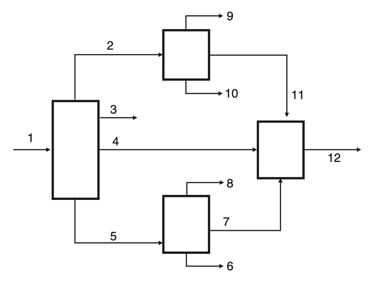

We can write this out as the system of equations


$$m_1 = m_2 + m_3 + m_4 + m_5\\
m_2 = m_9 + m_{10} + m_{11}\\
m_5 = m_8 + m_7 + m_6\\
m_{12} = m_4 + m_7 + m_{11}\\
m_1 = 100\\
m_5 = 5m_8\\
0.84m_{12} = m_4 + m_7\\
0.7m_1 = m_2 + m_3\\
0.55m_1 = m_9 + m_{12}\\
0.2m_9 = m_{10}\\
0.85m_2 = m_9 + m_{11}\\
3.2m_6 = m_7 + m_8$$


The first four equations are the mass balances; the next eight equations are the process specifications.

(a)    Write a MATLAB program that generates the matrix $\mathbf{A}$and the vector $\mathbf{b}$ required to solve the problem for this set of equations.

(b)    Use the MATLAB built-in function `linsolve` to solve this system of equations.

(c)    Write a MATLAB program that solves this system using naive Gauss elimination. What happens? How do you fix it?

### Problem 2

(a)    Does the following system have a unique solution, no solution or infinitely many solutions? You must prove your answer (*Hint: what condition guarantees that a system of equations has unique solution?*).


$$\left\lbrack \begin{array}{cccc}
6 & 1 & -2 & 3\\
2 & -2 & 4 & -1\\
1 & -1 & 1 & -1\\
0 & -2 & 2 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1\\
-1\\
4
\end{array}\right\rbrack$$


(b) If it has a solution, write MATLAB code for Gauss elimination with pivoting to solve the system.

### Problem 3

Solve the following system of linear equations by hand using

(a)    Gauss elimination

(b)    LU Decomposition


$$\left\lbrack \begin{array}{cccc}
6 & 1 & 0 & -3\\
-2 & 8 & 2 & 3\\
1 & -6 & 10 & -2\\
2 & 1 & 3 & 9
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-9\\
9\\
17\\
13
\end{array}\right\rbrack$$
	

### Problem 4 

Steam which is saturated at 130 ºC is flowing inside a cylindrical pipe made of steel with an inner diameter ($D_1$) of 20 mm and an outer diameter ($D_2
$) of 25 mm. Heat is transferred radially from the steam, across the steel pipe, across the insulation and into the outside air as depicted in Figure 1. The pipe is insulated with 50 mm ($(D_3-D_2)/2$) of outer insulation. The convective heat transfer coefficient for the inside steam to the steel pipe is $h_i = 1700~\mathrm{W}/(\mathrm{m}^2\mathrm{K})$ and the heat transfer coefficient for the outer insulation and open air is $h_o = 3~\mathrm{W}/(\mathrm{m}^2\mathrm{K})$, respectively. The thermal conductivity of the metal is $k_s = 45~\mathrm{W}/(\mathrm{m}\mathrm{K})$. The insulation has a thermal conductivity of $k_i = 0.064~\mathrm{W}/(\mathrm{m}\mathrm{K})$. The air temperature is 25 ºC.

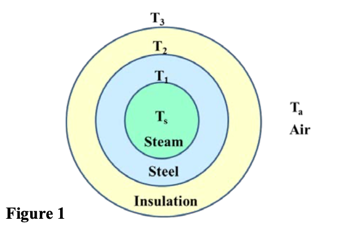 

One can write energy balances across each of the three interfaces to come up with the following expressions: 

1.    Heat transfer: Steam to pipe


$$h_i\pi D_1 (T_s - T_1) = \frac{T_1 - T_2}{\ln (D_2/D_1)/(2\pi k_s)}$$


2.    Heat transfer: Pipe to insulation


$$\frac{T_1 - T_2}{\ln (D_2/D_1)/(2\pi k_s)} = \frac{T_2 - T_3}{\ln (D_3/D_2)/(2\pi k_i)}$$


3.    Heat transfer: Insulation to the Air


$$\frac{T_2 - T_3}{\ln (D_3/D_2)/(2\pi k_i)} = h_o \pi D_3(T_3 - T_a)$$


Where

                                                                                        $T_s$ = temperature of the steam = 130 ºC

                                                                                        $T_1
$ = temperature of the inside wall of pipe

                                                                                        $T_2$ = temperature of outside wall of pipe

                                                                                        $T_3$ = temperature outside of insulation

                                                                                        $T_a$ = air temperature (25 ºC)

(a)    Please rearrange these equations to put them into the matrix form


$$\mathbf{A} \mathbf{x} = \mathbf{b}$$


(b)    Write a MATLAB program to solve the general linear equations 1-3 using Gauss Elimination where all of the input variables ($T_s, T_a, D_1, D_2, D_3, h_i, h_o, k_s,$ etc.) are specified near the top of the program.The program should solve for the temperatures $T_1$, $T_2$ and $T_3$. (You can use your code for Gauss elimination with pivoting from Problem 2).